clear all
load('D:\V1_Cortex_Paper\MultichannelDataTanks\lfp_by_layer_tables_with_ID.mat');

cutoff = 0.0002;
time_window = 783:1033;  % time window
to_remove = false(height(lfp_L4),1);  % logical index for rows to remove

for ch = 1:height(lfp_L4)
    % Extract LFP matrix for 'dev' condition (40x1879)
    lfp_matrix = lfp_L4.dev{ch};  % cell content
    
    % Compute peak-to-peak amplitude of the mean LFP across trials in time window
    mean_lfp = mean(lfp_matrix(:, time_window), 1); % average over trials
    p2p_amp = peak2peak(mean_lfp);
    
    % Mark channel if amplitude is below cutoff
    if p2p_amp < cutoff
        to_remove(ch) = true;
    end
end

% Remove low amplitude channels
lfp_L4(to_remove, :) = [];

%Create time vector
tempdev = lfp_L4.dev{1};  % example channel's deviant LFP matrix (40x1879)

% Number of time points
nTimePoints = size(tempdev, 2);

% Create time vector (ms)
timevector = (1:nTimePoints) / 0.626;  % sample rate: 0.626 ms per sample

% Adjust zero reference point (shift by 1000 ms)
timevector = timevector - 1000; 

stdSamps = 1:626;
devSamps = 626:1252;
postSamps = 1252:length(timevector);

% tempdev = lfp_L4.dev;
% tempdevmean = cellfun(@(x) mean(x, 1), tempdev, 'UniformOutput', false);
% tempdev = tempdevmean; 
% 
% tempdevP = lfp_L4.devPdev;
% tempdevPmean = cellfun(@(x) mean(x, 1), tempdevP, 'UniformOutput', false);
% tempdevP = tempdevPmean; 
% 
% tempctr = lfp_L4.ctr;
% tempctrmean = cellfun(@(x) mean(x, 1), tempctr, 'UniformOutput', false);
% tempctr = tempctrmean; 
% 
% tempdev = cell2mat(tempdev);
% tempdevP = cell2mat(tempdevP);
% tempctr = cell2mat(tempctr);

% % --- Parameters ---
% savpath = 'D:\Your\Save\Path';
% if ~exist(savpath, 'dir'), mkdir(savpath); end
% 
% % Color definitions
% red = [204, 37, 41]/255;
% blue = [0, 114, 189]/255;
% green = [57, 181, 74]/255;

% % --- Combined DEV and DEV-P with Shaded Error Bars ---
% figure; hold on;
% 
% % --- STD Segment ---
% SEM_STD = std(tempdev(:,stdSamps)) / sqrt(size(tempdev,1)) * 1000;
% shadedErrorBar(timevector(stdSamps), mean(tempdev(:,stdSamps))*1000, SEM_STD, 'lineProps', {'b','LineWidth',1.5});
% 
% % --- DEV Segment ---
% SEM_DEV = std(tempdev(:,devSamps)) / sqrt(size(tempdev,1)) * 1000;
% shadedErrorBar(timevector(devSamps), mean(tempdev(:,devSamps))*1000, SEM_DEV, 'lineProps', {'r','LineWidth',1.5});
% 
% % --- POST Segment ---
% SEM_POST = std(tempdev(:,postSamps)) / sqrt(size(tempdev,1)) * 1000;
% shadedErrorBar(timevector(postSamps), mean(tempdev(:,postSamps))*1000, SEM_POST, 'lineProps', {'k','LineWidth',1.5});
% 
% % --- Control ---
% SEM_CTR = std(tempctr) / sqrt(size(tempctr,1)) * 1000;
% shadedErrorBar(timevector, mean(tempctr)*1000, SEM_CTR, 'lineProps', {'g','LineWidth',1.5});
% 
% % Labels and styling
% ylim([-0.1 0.1]);
% xlabel('Time (ms)');
% ylabel('LFP (mV)');
% title('Mean Waveforms with SEM');
% legend({'STD','DEV','POST','CTR'},'Location','Best');
% 
% print(gcf, '-dpng', fullfile(savpath, 'DEV_Shaded_L4.png'));
% print(gcf, '-dpdf', fullfile(savpath, 'DEV_Shaded_L4.pdf'));
% 
% % --- Combined DEV and DEV-P with Shaded Error Bars ---
% figure; hold on;
% 
% % --- STD Segment ---
% SEM_STD_P = std(tempdevP(:,stdSamps)) / sqrt(size(tempdevP,1)) * 1000;
% shadedErrorBar(timevector(stdSamps), mean(tempdevP(:,stdSamps))*1000, SEM_STD_P, 'lineProps', {'b--','LineWidth',1.5});
% 
% % --- DEV Segment ---
% SEM_DEV_P = std(tempdevP(:,devSamps)) / sqrt(size(tempdevP,1)) * 1000;
% shadedErrorBar(timevector(devSamps), mean(tempdevP(:,devSamps))*1000, SEM_DEV_P, 'lineProps', {'r--','LineWidth',1.5});
% 
% % --- POST Segment ---
% SEM_POST_P = std(tempdevP(:,postSamps)) / sqrt(size(tempdevP,1)) * 1000;
% shadedErrorBar(timevector(postSamps), mean(tempdevP(:,postSamps))*1000, SEM_POST_P, 'lineProps', {'k--','LineWidth',1.5'});
% 
% % --- Control ---
% SEM_CTR = std(tempctr) / sqrt(size(tempctr,1)) * 1000;
% shadedErrorBar(timevector, mean(tempctr)*1000, SEM_CTR, 'lineProps', {'g','LineWidth',1.5});
% 
% % Labels and styling
% ylim([-0.1 0.1]);
% xlabel('Time (ms)');
% ylabel('LFP (mV)');
% title('Periodic Mean Waveforms with SEM');
% legend({'STD-P','DEV-P','POST-P','CTR'},'Location','Best');
% 
% print(gcf, '-dpng', fullfile(savpath, 'DEVp_Shaded_L4.png'));
% print(gcf, '-dpdf', fullfile(savpath, 'DEVp_Shaded_L4.pdf'));
% 
% % --- Combined DEV and DEV-P with Shaded Error Bars ---
% figure; hold on;
% 
% % --- STD Segment ---
% SEM_STD = std(tempdev(:,stdSamps)) / sqrt(size(tempdev,1)) * 1000;
% shadedErrorBar(timevector(stdSamps), mean(tempdev(:,stdSamps))*1000, SEM_STD, 'lineProps', {'b','LineWidth',1.5});
% 
% % --- DEV Segment ---
% SEM_DEV = std(tempdev(:,devSamps)) / sqrt(size(tempdev,1)) * 1000;
% shadedErrorBar(timevector(devSamps), mean(tempdev(:,devSamps))*1000, SEM_DEV, 'lineProps', {'r','LineWidth',1.5});
% 
% % --- POST Segment ---
% SEM_POST = std(tempdev(:,postSamps)) / sqrt(size(tempdev,1)) * 1000;
% shadedErrorBar(timevector(postSamps), mean(tempdev(:,postSamps))*1000, SEM_POST, 'lineProps', {'k','LineWidth',1.5});
% 
% % --- STD Segment ---
% SEM_STD_P = std(tempdevP(:,stdSamps)) / sqrt(size(tempdevP,1)) * 1000;
% shadedErrorBar(timevector(stdSamps), mean(tempdevP(:,stdSamps))*1000, SEM_STD_P, 'lineProps', {'b--','LineWidth',1.5});
% 
% % --- DEV Segment ---
% SEM_DEV_P = std(tempdevP(:,devSamps)) / sqrt(size(tempdevP,1)) * 1000;
% shadedErrorBar(timevector(devSamps), mean(tempdevP(:,devSamps))*1000, SEM_DEV_P, 'lineProps', {'r--','LineWidth',1.5});
% 
% % --- POST Segment ---
% SEM_POST_P = std(tempdevP(:,postSamps)) / sqrt(size(tempdevP,1)) * 1000;
% shadedErrorBar(timevector(postSamps), mean(tempdevP(:,postSamps))*1000, SEM_POST_P, 'lineProps', {'k--','LineWidth',1.5'});
% 
% % Labels and styling
% ylim([-0.1 0.1]);
% xlabel('Time (ms)');
% ylabel('LFP (mV)');
% title('Periodic vs Random Mean Waveforms with SEM');
% legend({'STD','DEV','POST','CTR'},'Location','Best');
% 
% print(gcf, '-dpng', fullfile(savpath, 'RvsP_Shaded_L4.png'));
% print(gcf, '-dpdf', fullfile(savpath, 'RvsP_Shaded_L4.pdf'));

% 
% % --- Combined DEV and DEV-P with Shaded Error Bars ---
% figure; hold on;
% 
% % --- STD Segment ---
% SEM_STD = std(tempdev(:,stdSamps)) / sqrt(size(tempdev,1)) * 1000;
% shadedErrorBar(timevector(devSamps), mean(tempdev(:,stdSamps(:,[1:626])))*1000, SEM_STD, 'lineProps', {'b','LineWidth',1.5});
% 
% % --- DEV Segment ---
% SEM_DEV = std(tempdev(:,devSamps)) / sqrt(size(tempdev,1)) * 1000;
% shadedErrorBar(timevector(devSamps), mean(tempdev(:,devSamps))*1000, SEM_DEV, 'lineProps', {'r','LineWidth',1.5});
% 
% % Labels and styling
% ylim([-0.1 0.1]);
% xlabel('Time (ms)');
% ylabel('LFP (mV)');
% title('Periodic vs Random Mean Waveforms with SEM');
% legend({'STD','DEV','POST','CTR'},'Location','Best');
% 
% print(gcf, '-dpng', fullfile(savpath, 'DEV_DEVp_Shaded.png'));
% print(gcf, '-dpdf', fullfile(savpath, 'DEVp_Shaded.pdf'));

% % --- 2) Bar plot with SEM ---
% % Compute peak-to-peak amplitudes (you already have these)
% ampsstd = peak2peak(tempdev(:,156:406)')';
% ampsstdP = peak2peak(tempdevP(:,156:406)')';
% 
% ampsdev = peak2peak(tempdev(:,783:1033)')';
% ampsdevP = peak2peak(tempdevP(:,783:1033)')';
% 
% ampsctr = peak2peak(tempctr(:,156:406)')';
% 
% % Prepare categorical x-axis
% x = categorical({'STD', 'DEV', 'CTR'});
% x = reordercats(x, {'STD', 'DEV', 'CTR'});
% 
% % Means & SEMs for two groups (original and P)
% y = [mean(ampsstd), mean(ampsstdP);
%      mean(ampsdev), mean(ampsdevP);
%      mean(ampsctr), 0] * 1000;  % convert to mV
% 
% sem = [std(ampsstd)/sqrt(length(ampsstd)), std(ampsstdP)/sqrt(length(ampsstdP));
%        std(ampsdev)/sqrt(length(ampsdev)), std(ampsdevP)/sqrt(length(ampsdevP));
%        std(ampsctr)/sqrt(length(ampsctr)), 0] * 1000;
% 
% % Plot bar graph
% figure;
% b = bar(x, y, 'grouped'); 
% hold on;
% ylim([0 0.25]);
% 
% % Define colors for each group (STD, DEV, CTR) for each bar set
% blue = [0, 0.4470, 0.7410];
% red = [0.8500, 0.3250, 0.0980];
% green = [0.4660, 0.6740, 0.1880];
% 
% % First group bars (original)
% b(1).FaceColor = 'flat';
% b(1).CData(1,:) = blue;   % STD
% b(1).CData(2,:) = red;    % DEV
% b(1).CData(3,:) = green;  % CTR
% 
% % Second group bars (P)
% b(2).FaceColor = 'flat';
% b(2).CData(1,:) = blue * 0.6;   % slightly lighter blue for P
% b(2).CData(2,:) = red * 0.6;    % slightly lighter red for P
% b(2).CData(3,:) = green * 0.6;  % slightly lighter green for P (will be zero)
% 
% % Calculate bar centers for error bars
% ctrs = nan(size(y));
% ydt = nan(size(y));
% for k = 1:2
%     ctrs(:,k) = b(k).XEndPoints;
%     ydt(:,k) = b(k).YData;
% end
% 
% % Plot SEM error bars
% errorbar(ctrs, ydt, sem, 'k.', 'LineWidth', 1.5);
% 
% ylabel('Peak-to-peak amplitude (mV)');
% title('Amplitude Comparison');
% hold off;
% 
% % Stats
% [p_std,~]=signrank(ampsstd,ampsstdP);
% [p_dev,~]=signrank(ampsdev,ampsdevP);
% pvals = [p_std, p_dev];
% sigstar({[1 2],[3 4]}, pvals);
% print(gcf, '-dpng', fullfile(savpath, 'Amplitude_Bars_L4.png'));
% print(gcf, '-dpdf', fullfile(savpath, 'Amplitude_Bars_L4.pdf'));
% 
% % --- 3) Violin Plot ---
% figure;
% 
% % Euclidean normalization
% euclidnorm = sqrt(ampsdev.^2 + ampsstd.^2 + ampsctr.^2);
% euclidnormP = sqrt(ampsdevP.^2 + ampsstdP.^2 + ampsctr.^2);
% 
% ampsdev_n = ampsdev ./ euclidnorm;
% ampsctr_n = ampsctr ./ euclidnorm;
% ampsstd_n = ampsstd ./ euclidnorm;
% 
% ampsdevP_n = ampsdevP ./ euclidnormP;
% ampsstdP_n = ampsstdP ./ euclidnormP;
% 
% iPE = ampsdev_n - ampsctr_n;
% iRS = ampsctr_n - ampsstd_n;
% iPEp = ampsdevP_n - ampsctr_n;
% iRSp = ampsctr_n - ampsstdP_n;
% 
% iMM = iPE + iRS;
% iMMp = iPEp + iRSp;
% 
% violindata = [iPE, iPEp, iRS, iRSp, iMM, iMMp];
% vpColors = [
%     255 204 0;    % Yellow for iPE
%     255 204 0;    % Yellow for iPEp
%     0 153 255;    % Blue for iRS
%     0 153 255;    % Blue for iRSp
%     255 0 255;    % Magenta for iMM
%     255 0 255     % Magenta for iMMp
% ] / 255;
% 
% % Directly specify colors during violinplot call
% violinplot(violindata, {'iPE','iPEp','iRS','iRSp','iMM','iMMp'}, 'ViolinColor', vpColors);
% 
% ylim([-0.6 1]);
% 
% ylabel('Mismatch Index');
% title('Mismatch Indices');
% [p_violin, tbl, stats] = kruskalwallis(violindata, [], 'off');
% print(gcf, '-dpng', fullfile(savpath, 'Violin_Mismatch_L4.png'));
% print(gcf, '-dpdf', fullfile(savpath, 'Violin_Mismatch_L4.pdf'));

tempdev = lfp_L5.dev;
tempdevmean = cellfun(@(x) mean(x, 1), tempdev, 'UniformOutput', false);
tempdev = tempdevmean; 

tempdevP = lfp_L5.devPdev;
tempdevPmean = cellfun(@(x) mean(x, 1), tempdevP, 'UniformOutput', false);
tempdevP = tempdevPmean; 

tempctr = lfp_L5.ctr;
tempctrmean = cellfun(@(x) mean(x, 1), tempctr, 'UniformOutput', false);
tempctr = tempctrmean; 

tempdev = cell2mat(tempdev);
tempdevP = cell2mat(tempdevP);
tempctr = cell2mat(tempctr);

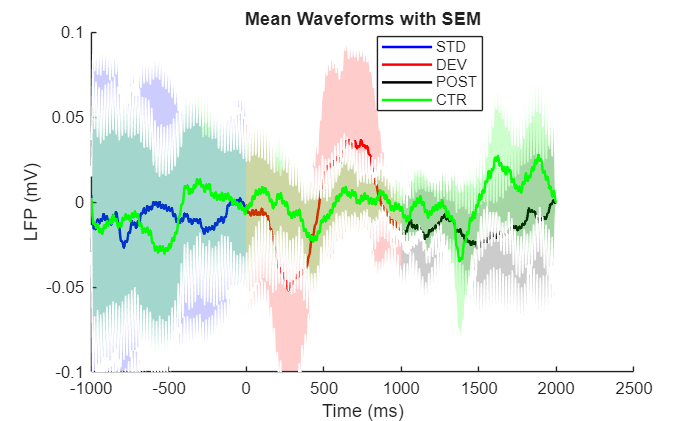

% --- Parameters ---
savpath = 'D:\Your\Save\Path';
if ~exist(savpath, 'dir'), mkdir(savpath); end

% Color definitions
red = [204, 37, 41]/255;
blue = [0, 114, 189]/255;
green = [57, 181, 74]/255;

% --- Combined DEV, STD and CTR with Shaded Error Bars ---
figure; hold on;

% --- STD Segment ---
SEM_STD = std(tempdev(:,stdSamps)) / sqrt(size(tempdev,1)) * 1000;
% SEM_STD = std(tempdev(:,stdSamps)) * 1000;
shadedErrorBar(timevector(stdSamps), mean(tempdev(:,stdSamps))*1000, SEM_STD, 'lineProps', {'b','LineWidth',1.5});

% --- DEV Segment ---
SEM_DEV = std(tempdev(:,devSamps)) / sqrt(size(tempdev,1)) * 1000;
% SEM_DEV = std(tempdev(:,devSamps)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdev(:,devSamps))*1000, SEM_DEV, 'lineProps', {'r','LineWidth',1.5});

% --- POST Segment ---
SEM_POST = std(tempdev(:,postSamps)) / sqrt(size(tempdev,1)) * 1000;
% SEM_POST = std(tempdev(:,postSamps)) * 1000;
shadedErrorBar(timevector(postSamps), mean(tempdev(:,postSamps))*1000, SEM_POST, 'lineProps', {'k','LineWidth',1.5});

% --- Control ---
SEM_CTR = std(tempctr) / sqrt(size(tempctr,1)) * 1000;
% SEM_CTR = std(tempctr) * 1000;
shadedErrorBar(timevector, mean(tempctr)*1000, SEM_CTR, 'lineProps', {'g','LineWidth',1.5});

% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('Mean Waveforms with SEM');
legend({'STD','DEV','POST','CTR'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'DEV_Shaded_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'DEV_Shaded_L5.pdf'));

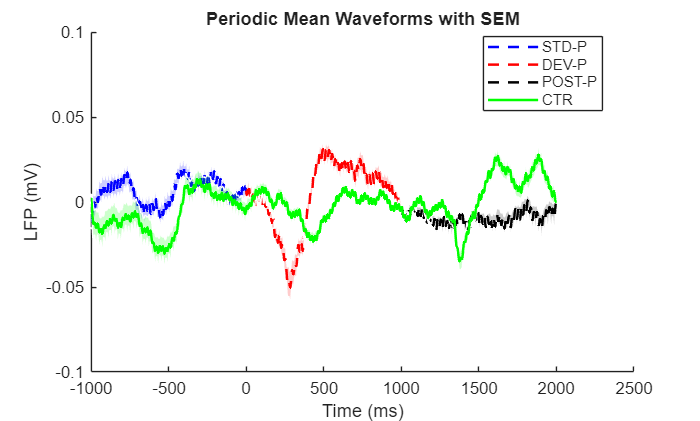


% --- Combined DEV and DEV-P with Shaded Error Bars ---
figure; hold on;

% --- STD Segment ---
SEM_STD_P = std(tempdevP(:,stdSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(stdSamps), mean(tempdevP(:,stdSamps))*1000, SEM_STD_P, 'lineProps', {'b--','LineWidth',1.5});

% --- DEV Segment ---
SEM_DEV_P = std(tempdevP(:,devSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdevP(:,devSamps))*1000, SEM_DEV_P, 'lineProps', {'r--','LineWidth',1.5});

% --- POST Segment ---
SEM_POST_P = std(tempdevP(:,postSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(postSamps), mean(tempdevP(:,postSamps))*1000, SEM_POST_P, 'lineProps', {'k--','LineWidth',1.5'});

% --- Control ---
SEM_CTR = std(tempctr) / sqrt(size(tempctr,1)) * 1000;
shadedErrorBar(timevector, mean(tempctr)*1000, SEM_CTR, 'lineProps', {'g','LineWidth',1.5});

% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('Periodic Mean Waveforms with SEM');
legend({'STD-P','DEV-P','POST-P','CTR'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'DEVp_Shaded_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'DEVp_Shaded_L5.pdf'));

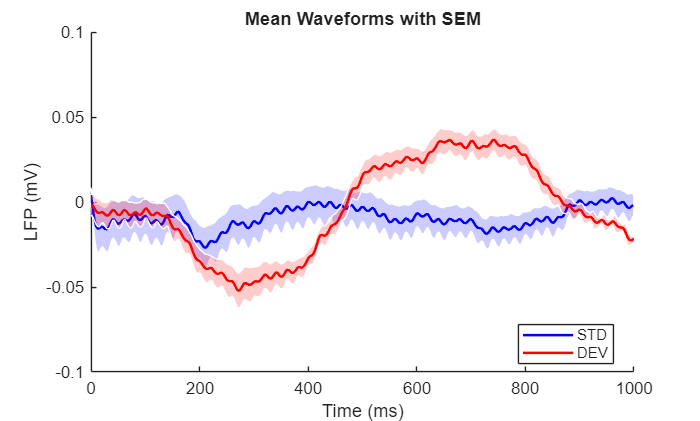



% --- Combined DEV and STD with Shaded Error Bars ---
figure; hold on;

% --- STD Segment ---
SEM_STD = std(tempdev(:,stdSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(devSamps(1:626)), mean(tempdev(:,stdSamps))*1000, SEM_STD, 'lineProps', {'b','LineWidth',1.5});

% --- DEV Segment ---
SEM_DEV = std(tempdev(:,devSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdev(:,devSamps))*1000, SEM_DEV, 'lineProps', {'r','LineWidth',1.5});


% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('Mean Waveforms with SEM');
legend({'STD','DEV'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'DEV_STD_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'DEV_STD_L5.pdf'));


% --- MMN with Shaded Error Bars ---
figure; hold on;
DEV = tempdev(:,devSamps(1:626)).*1000;
STD =  tempdev(:,stdSamps).*1000;
MMN = mean(DEV) - mean(STD);
SEM_MMN = SEM_DEV(1:626) + SEM_STD;

% --- MMN Segment ---
shadedErrorBar(timevector(devSamps(1:626)), MMN, SEM_MMN, 'lineProps', {'k','LineWidth',1.5});


% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('MMN with SEM');
legend({'STD','DEV'},'Location','Best');

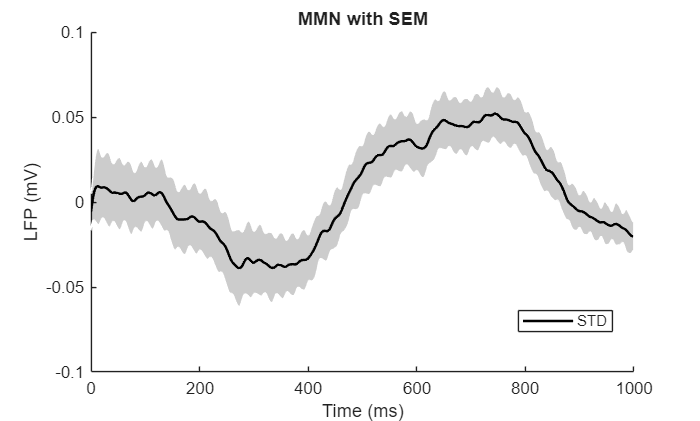


print(gcf, '-dpng', fullfile(savpath, 'MMN_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'MMN_L5.pdf'));

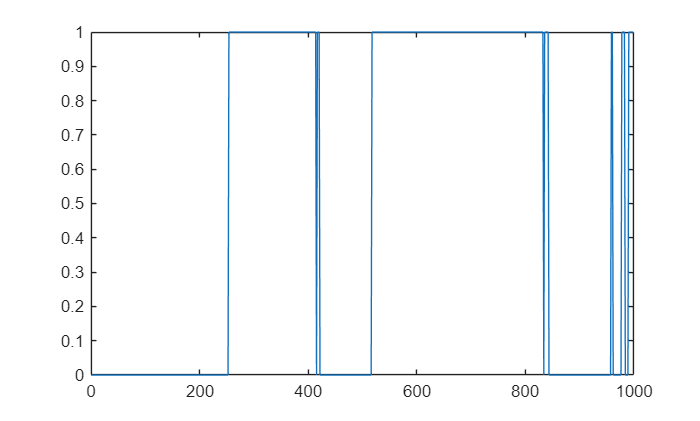


clear h p
for i = 1:size(STD,2)
    [h(i), p(i)] = ttest2(DEV(:,i),STD(:,i));
end
figure
plot(timevector(devSamps(1:626)),h)

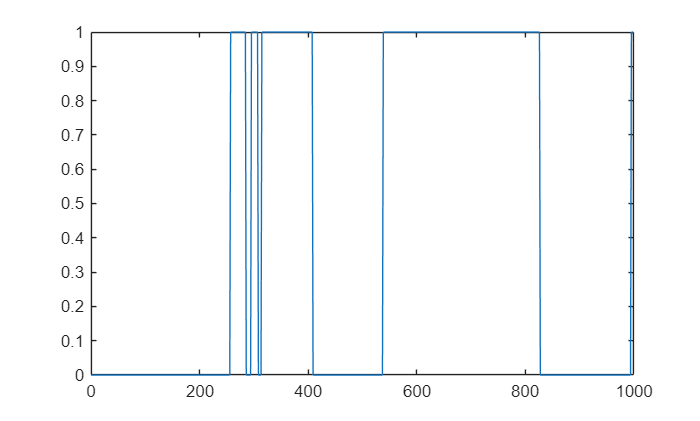

[c_pvalues, c_alpha, h, extra] = fdr_BH(p, 0.05);
figure
plot(timevector(devSamps(1:626)),h)

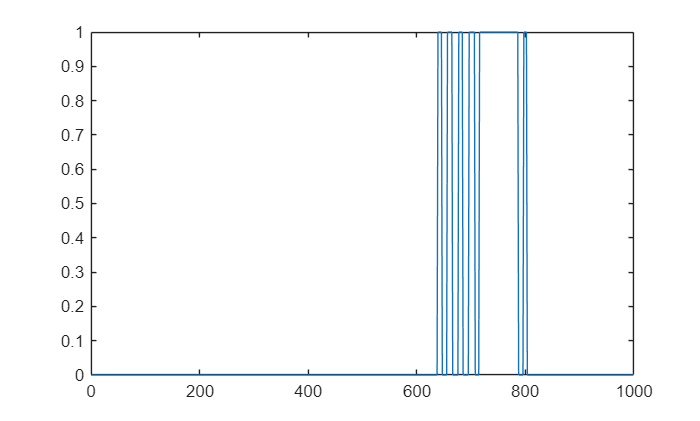

 [c_pvalues, c_alpha, h] = fwer_sidak(p, 0.05);
figure
plot(timevector(devSamps(1:626)),h)

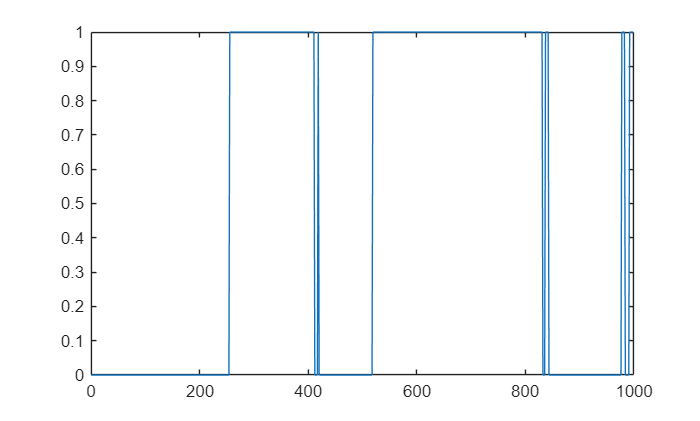

[c_pvalues, chi2_2k, h, extra] = mt_fisher(p, 0.01);
figure
plot(timevector(devSamps(1:626)),h)

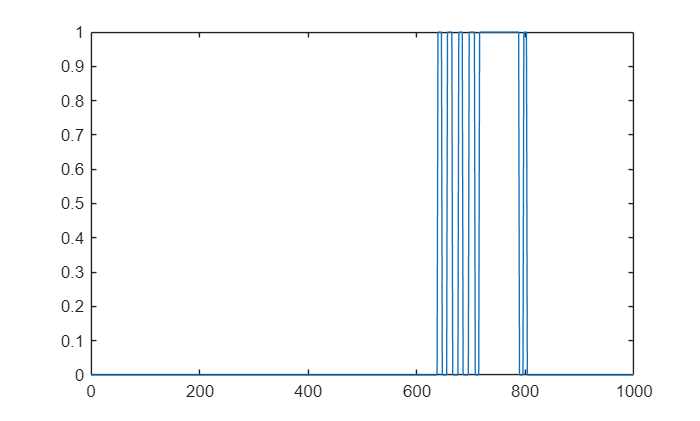

[c_pvalues, ~, h] = fwer_holmbonf(p, 0.05);
figure
plot(timevector(devSamps(1:626)),h)
print(gcf, '-dpng', fullfile(savpath, 'Error_h_holmbonf_MMN_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Error_h_holmbonf_MMN_L5.pdf'));

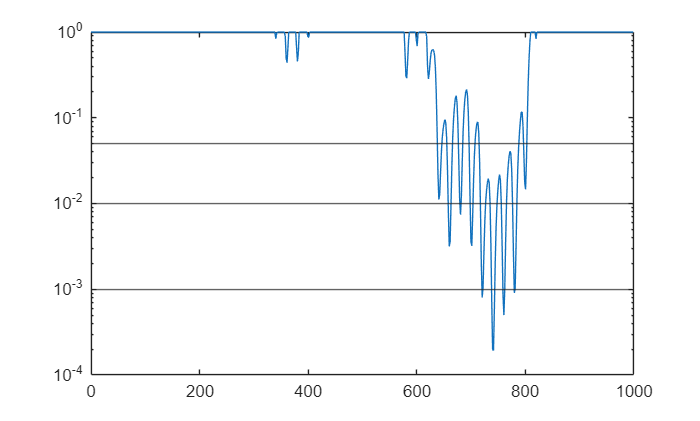


figure
plot(timevector(devSamps(1:626)),c_pvalues)
yline(0.05)
yline(0.01)
yline(0.001)
set(gca, 'YScale', 'log')
print(gcf, '-dpng', fullfile(savpath, 'Error_c_holmbonf_MMN_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Error_c_holmbonf_MMN_L5.pdf'));

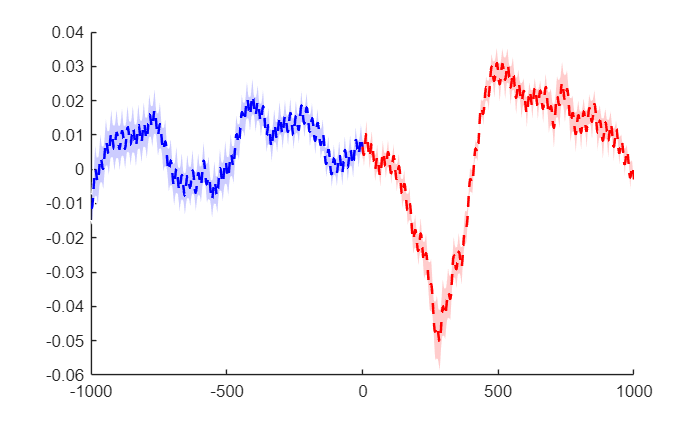



% --- Combined DEV and DEV-P with Shaded Error Bars ---
figure; hold on;

% --- STD Segment ---
SEM_STD_P = std(tempdevP(:,stdSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(stdSamps), mean(tempdevP(:,stdSamps))*1000, SEM_STD_P, 'lineProps', {'b--','LineWidth',1.5});

% --- DEV Segment ---
SEM_DEV_P = std(tempdevP(:,devSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdevP(:,devSamps))*1000, SEM_DEV_P, 'lineProps', {'r--','LineWidth',1.5});


% --- POST Segment ---
SEM_POST_P = std(tempdevP(:,postSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(postSamps), mean(tempdevP(:,postSamps))*1000, SEM_POST_P, 'lineProps', {'k--','LineWidth',1.5'});

% --- Control ---
SEM_CTR = std(tempctr) / sqrt(size(tempctr,1)) * 1000;
shadedErrorBar(timevector, mean(tempctr)*1000, SEM_CTR, 'lineProps', {'g','LineWidth',1.5});

% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('Periodic Mean Waveforms with SEM');
legend({'STD-P','DEV-P','POST-P','CTR'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'DEVp_Shaded_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'DEVp_Shaded_L5.pdf'));


% --- Combined DEV and DEV-P with Shaded Error Bars ---
figure; hold on;

% --- STD Segment ---
SEM_STD = std(tempdev(:,stdSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(stdSamps), mean(tempdev(:,stdSamps))*1000, SEM_STD, 'lineProps', {'b','LineWidth',1.5});

% --- DEV Segment ---
SEM_DEV = std(tempdev(:,devSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdev(:,devSamps))*1000, SEM_DEV, 'lineProps', {'r','LineWidth',1.5});

% --- POST Segment ---
SEM_POST = std(tempdev(:,postSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(postSamps), mean(tempdev(:,postSamps))*1000, SEM_POST, 'lineProps', {'k','LineWidth',1.5});

% --- STD Periodic Segment ---
SEM_STD_P = std(tempdevP(:,stdSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(stdSamps), mean(tempdevP(:,stdSamps))*1000, SEM_STD_P, 'lineProps', {'b--','LineWidth',1.5});

% --- DEV Periodic Segment ---
SEM_DEV_P = std(tempdevP(:,devSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdevP(:,devSamps))*1000, SEM_DEV_P, 'lineProps', {'r--','LineWidth',1.5});

% --- POST Periodic Segment ---
SEM_POST_P = std(tempdevP(:,postSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(postSamps), mean(tempdevP(:,postSamps))*1000, SEM_POST_P, 'lineProps', {'k--','LineWidth',1.5'});

% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('Periodic vs Random Mean Waveforms with SEM');
legend({'STD','DEV','POST','CTR'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'RvsP_Shaded_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'RvsP_Shaded_L5.pdf'));

% Concatenate STD, DEV, POST segments for random condition
full_tempdev = [tempdev(:, stdSamps), tempdev(:, devSamps), tempdev(:, postSamps)];

% Concatenate STD, DEV, POST segments for periodic condition
full_tempdevP = [tempdevP(:, stdSamps), tempdevP(:, devSamps), tempdevP(:, postSamps)];

% Create unified time vector
full_timevector = [timevector(stdSamps), timevector(devSamps), timevector(postSamps)];

% Optional: convert to mV
full_tempdev = full_tempdev * 1000;
full_tempdevP = full_tempdevP * 1000;

% Initialize t-test results
h = zeros(1, size(full_tempdev, 2));
p = zeros(1, size(full_tempdev, 2));
clear h p
% Loop through each time point and apply t-test
for i = 1:size(full_tempdev, 2)
    [h(i), p(i)] = ttest2(full_tempdev(:, i), full_tempdevP(:, i));
end

figure
plot(full_timevector,h)
[c_pvalues, c_alpha, h, extra] = fdr_BH(p, 0.05);
figure
plot(full_timevector,h)
 [c_pvalues, c_alpha, h] = fwer_sidak(p, 0.05);
figure
plot(full_timevector,h)
[c_pvalues, chi2_2k, h, extra] = mt_fisher(p, 0.01);
figure
plot(full_timevector,h)
[c_pvalues, ~, h] = fwer_holmbonf(p, 0.05);
figure
plot(full_timevector,h)
print(gcf, '-dpng', fullfile(savpath, 'Error_h_holmbonf_PvsR_L5.png'));
print(gcf,'-dpdf', fullfile(savpath, 'Error_h_holmbonf_PvsR_L5.pdf'));

figure
plot(full_timevector,c_pvalues)
yline(0.05)
yline(0.01)
yline(0.001)
set(gca, 'YScale', 'log')
print(gcf, '-dpng', fullfile(savpath, 'Error_c_holmbonf_PvsR_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Error_c_holmbonf_PvsR_L5.pdf'));



% --- 2) Bar plot with SEM ---
% Compute peak-to-peak amplitudes (you already have these)
ampsstd = peak2peak(tempdev(:,156:406)')';
ampsstdP = peak2peak(tempdevP(:,156:406)')';

ampsdev = peak2peak(tempdev(:,783:1033)')';
ampsdevP = peak2peak(tempdevP(:,783:1033)')';

ampsctr = peak2peak(tempctr(:,156:406)')';

% Prepare categorical x-axis
x = categorical({'STD', 'DEV', 'CTR'});
x = reordercats(x, {'STD', 'DEV', 'CTR'});

% Means & SEMs for two groups (original and P)
y = [mean(ampsstd), mean(ampsstdP);
     mean(ampsdev), mean(ampsdevP);
     mean(ampsctr), 0] * 1000;  % convert to mV

sem = [std(ampsstd)/sqrt(length(ampsstd)), std(ampsstdP)/sqrt(length(ampsstdP));
       std(ampsdev)/sqrt(length(ampsdev)), std(ampsdevP)/sqrt(length(ampsdevP));
       std(ampsctr)/sqrt(length(ampsctr)), 0] * 1000;

% Plot bar graph
figure;
b = bar(x, y, 'grouped'); 
hold on;
ylim([0 0.25]);

% Define colors for each group (STD, DEV, CTR) for each bar set
blue = [0, 0.4470, 0.7410];
red = [0.8500, 0.3250, 0.0980];
green = [0.4660, 0.6740, 0.1880];

% First group bars (original)
b(1).FaceColor = 'flat';
b(1).CData(1,:) = blue;   % STD
b(1).CData(2,:) = red;    % DEV
b(1).CData(3,:) = green;  % CTR

% Second group bars (P)
b(2).FaceColor = 'flat';
b(2).CData(1,:) = blue * 0.6;   % slightly lighter blue for P
b(2).CData(2,:) = red * 0.6;    % slightly lighter red for P
b(2).CData(3,:) = green * 0.6;  % slightly lighter green for P (will be zero)

% Calculate bar centers for error bars
ctrs = nan(size(y));
ydt = nan(size(y));
for k = 1:2
    ctrs(:,k) = b(k).XEndPoints;
    ydt(:,k) = b(k).YData;
end

% Plot SEM error bars
errorbar(ctrs, ydt, sem, 'k.', 'LineWidth', 1.5);

ylabel('Peak-to-peak amplitude (mV)');
title('Amplitude Comparison');
hold off;

% Stats
% Raw p-values
[p_std_dev, ~] = signrank(ampsstd, ampsdev);
[p_dev_ctr, ~] = signrank(ampsdev, ampsctr);
[p_std_ctr, ~] = signrank(ampsstd, ampsctr);

[p_stdP_devP, ~] = signrank(ampsstdP, ampsdevP);
[p_devP_ctr, ~] = signrank(ampsdevP, ampsctr);
[p_stdP_ctr, ~] = signrank(ampsstdP, ampsctr);

[p_std_stdP, ~] = signrank(ampsstd, ampsstdP);
[p_dev_devP, ~] = signrank(ampsdev, ampsdevP);

% Collect p-values in a vector
p_raw = [p_std_dev; p_dev_ctr; p_std_ctr; ...
         p_stdP_devP; p_devP_ctr; p_stdP_ctr; ...
         p_std_stdP; p_dev_devP];

% Apply Bonferroni correction
p_bonf = min(p_raw * length(p_raw), 1);  % Correct and cap at 1

% Comparison labels
labels = {...
    'std vs dev', ...
    'dev vs ctr', ...
    'std vs ctr', ...
    'stdP vs devP', ...
    'devP vs ctr', ...
    'stdP vs ctr', ...
    'std vs stdP', ...
    'dev vs devP'};

% Create table
statsTable = table(labels', p_raw, p_bonf, ...
                   'VariableNames', {'Comparison', 'p_value', 'p_bonf'});

% Display table
disp(statsTable);

print(gcf, '-dpng', fullfile(savpath, 'Amplitude_Bars_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Amplitude_Bars_L5.pdf'));

% --- 3) Violin Plot ---
figure;

% Euclidean normalization
euclidnorm = sqrt(ampsdev.^2 + ampsstd.^2 + ampsctr.^2);
euclidnormP = sqrt(ampsdevP.^2 + ampsstdP.^2 + ampsctr.^2);

ampsdev_n = ampsdev ./ euclidnorm;
ampsctr_n = ampsctr ./ euclidnorm;
ampsstd_n = ampsstd ./ euclidnorm;

ampsdevP_n = ampsdevP ./ euclidnormP;
ampsstdP_n = ampsstdP ./ euclidnormP;

iPE = ampsdev_n - ampsctr_n;
iRS = ampsctr_n - ampsstd_n;
iPEp = ampsdevP_n - ampsctr_n;
iRSp = ampsctr_n - ampsstdP_n;

iMM = iPE + iRS;
iMMp = iPEp + iRSp;

violindata = [iPE, iPEp, iRS, iRSp, iMM, iMMp];
vpColors = [
    255 204 0;    % Yellow for iPE
    255 204 0;    % Yellow for iPEp
    0 153 255;    % Blue for iRS
    0 153 255;    % Blue for iRSp
    255 0 255;    % Magenta for iMM
    255 0 255     % Magenta for iMMp
] / 255;

% Directly specify colors during violinplot call
violinplot(violindata, {'iPE','iPEp','iRS','iRSp','iMM','iMMp'}, 'ViolinColor', vpColors);

ylim([-0.6 1]);

ylabel('Mismatch Index');
title('Mismatch Indices');
[p_violin, tbl, stats] = kruskalwallis(violindata, [], 'off')
print(gcf, '-dpng', fullfile(savpath, 'Violin_Mismatch_L5.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Violin_Mismatch_L5.pdf'));

% Violin plot data (each column is a condition)
violindata = {iPE, iPEp, iRS, iRSp, iMM, iMMp};
labels = {'iPE','iPEp','iRS','iRSp','iMM','iMMp'};
n = numel(violindata);

% Preallocate
p_values = zeros(n,1);
t_values = zeros(n,1);
h_values = zeros(n,1);

% Perform one-sample t-test for each
for i = 1:n
    [h_values(i), p_values(i), ~, stats] = ttest(violindata{i}, 0);
    t_values(i) = stats.tstat;
end

% Holm-Bonferroni correction
[sorted_p, sort_idx] = sort(p_values);
holm_thresholds = (1:n)' * 0;  % placeholder for actual thresholds
alpha = 0.05;
holm_thresholds = alpha ./ (n - (0:n-1))';

h_corrected = false(n,1);
for k = 1:n
    if sorted_p(k) <= holm_thresholds(k)
        h_corrected(sort_idx(k)) = true;
    else
        break;  % Holm-Bonferroni stops at first non-significant
    end
end

% Create table
holmTable = table(labels', t_values, p_values, h_corrected, ...
                  'VariableNames', {'Index', 't_stat', 'p_value', 'Significant_Holm'});

% Display
disp(holmTable);


% Define data and labels
violindata = {iPE, iPEp, iRS, iRSp, iMM, iMMp};
labels = {'iPE','iPEp','iRS','iRSp','iMM','iMMp'};
n = numel(violindata);

% Preallocate for results
comparisons = {};
p_raw = [];

% Pairwise comparisons
for i = 1:n-1
    for j = i+1:n
        % Store label and p-value
        comparisons{end+1,1} = sprintf('%s vs %s', labels{i}, labels{j});
        p_raw(end+1,1) = signrank(violindata{i}, violindata{j});
    end
end

% Bonferroni correction
p_bonf = min(p_raw * length(p_raw), 1);

% Create table
pairwiseTable = table(comparisons, p_raw, p_bonf, ...
                      'VariableNames', {'Comparison', 'p_value', 'p_bonferroni'});

% Display table
disp(pairwiseTable);

% Do the first cells first
tempdev = lfp_L6.dev;
tempdevmean = cellfun(@(x) mean(x, 1), tempdev, 'UniformOutput', false);
tempdev = tempdevmean; 

tempdevP = lfp_L6.devPdev;
tempdevPmean = cellfun(@(x) mean(x, 1), tempdevP, 'UniformOutput', false);
tempdevP = tempdevPmean; 

tempctr = lfp_L6.ctr;
tempctrmean = cellfun(@(x) mean(x, 1), tempctr, 'UniformOutput', false);
tempctr = tempctrmean; 

tempdev = cell2mat(tempdev);
tempdevP = cell2mat(tempdevP);
tempctr = cell2mat(tempctr);

% --- Parameters ---
savpath = 'D:\Your\Save\Path';
if ~exist(savpath, 'dir'), mkdir(savpath); end

% Color definitions
red = [204, 37, 41]/255;
blue = [0, 114, 189]/255;
green = [57, 181, 74]/255;

% --- Combined DEV, STD and CTR with Shaded Error Bars ---
figure; hold on;

% --- STD Segment ---
SEM_STD = std(tempdev(:,stdSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(stdSamps), mean(tempdev(:,stdSamps))*1000, SEM_STD, 'lineProps', {'b','LineWidth',1.5});

% --- DEV Segment ---
SEM_DEV = std(tempdev(:,devSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdev(:,devSamps))*1000, SEM_DEV, 'lineProps', {'r','LineWidth',1.5});

% --- POST Segment ---
SEM_POST = std(tempdev(:,postSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(postSamps), mean(tempdev(:,postSamps))*1000, SEM_POST, 'lineProps', {'k','LineWidth',1.5});

% --- Control ---
SEM_CTR = std(tempctr) / sqrt(size(tempctr,1)) * 1000;
shadedErrorBar(timevector, mean(tempctr)*1000, SEM_CTR, 'lineProps', {'g','LineWidth',1.5});

% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('Mean Waveforms with SEM');
legend({'STD','DEV','POST','CTR'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'DEV_Shaded_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'DEV_Shaded_L6.pdf'));

% --- Combined DEV and DEV-P with Shaded Error Bars ---
figure; hold on;

% --- STD Segment ---
SEM_STD_P = std(tempdevP(:,stdSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(stdSamps), mean(tempdevP(:,stdSamps))*1000, SEM_STD_P, 'lineProps', {'b--','LineWidth',1.5});

% --- DEV Segment ---
SEM_DEV_P = std(tempdevP(:,devSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdevP(:,devSamps))*1000, SEM_DEV_P, 'lineProps', {'r--','LineWidth',1.5});

% --- POST Segment ---
SEM_POST_P = std(tempdevP(:,postSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(postSamps), mean(tempdevP(:,postSamps))*1000, SEM_POST_P, 'lineProps', {'k--','LineWidth',1.5'});

% --- Control ---
SEM_CTR = std(tempctr) / sqrt(size(tempctr,1)) * 1000;
shadedErrorBar(timevector, mean(tempctr)*1000, SEM_CTR, 'lineProps', {'g','LineWidth',1.5});

% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('Periodic Mean Waveforms with SEM');
legend({'STD-P','DEV-P','POST-P','CTR'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'DEVp_Shaded_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'DEVp_Shaded_L6.pdf'));


% --- Combined DEV and STD with Shaded Error Bars ---
figure; hold on;

% --- STD Segment ---
SEM_STD = std(tempdev(:,stdSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(devSamps(1:626)), mean(tempdev(:,stdSamps))*1000, SEM_STD, 'lineProps', {'b','LineWidth',1.5});

% --- DEV Segment ---
SEM_DEV = std(tempdev(:,devSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdev(:,devSamps))*1000, SEM_DEV, 'lineProps', {'r','LineWidth',1.5});


% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('Mean Waveforms with SEM');
legend({'STD','DEV'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'DEV_STD_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'DEV_STD_L6.pdf'));

% --- MMN with Shaded Error Bars ---
figure; hold on;
DEV = tempdev(:,devSamps(1:626)).*1000;
STD =  tempdev(:,stdSamps).*1000;
MMN = mean(DEV) - mean(STD);
SEM_MMN = SEM_DEV(1:626) + SEM_STD;

% --- MMN Segment ---
shadedErrorBar(timevector(devSamps(1:626)), MMN, SEM_MMN, 'lineProps', {'k','LineWidth',1.5});


% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('MMN with SEM');
legend({'STD','DEV'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'MMN_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'MMN_L6.pdf'));

clear h p
for i = 1:size(STD,2)
    [h(i), p(i)] = ttest2(DEV(:,i),STD(:,i));
end
figure
plot(timevector(devSamps(1:626)),h)
[c_pvalues, c_alpha, h, extra] = fdr_BH(p, 0.05);
figure
plot(timevector(devSamps(1:626)),h)
 [c_pvalues, c_alpha, h] = fwer_sidak(p, 0.05);
figure
plot(timevector(devSamps(1:626)),h)
[c_pvalues, chi2_2k, h, extra] = mt_fisher(p, 0.01);
figure
plot(timevector(devSamps(1:626)),h)
[c_pvalues, ~, h] = fwer_holmbonf(p, 0.05);
figure
plot(timevector(devSamps(1:626)),h)
print(gcf, '-dpng', fullfile(savpath, 'Error_h_holmbonf_MMN_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Error_h_holmbonf_MMN_L6.pdf'));

figure
plot(timevector(devSamps(1:626)),c_pvalues)
yline(0.05)
yline(0.01)
yline(0.001)
set(gca, 'YScale', 'log')
print(gcf, '-dpng', fullfile(savpath, 'Error_c_holmbonf_MMN_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Error_c_holmbonf_MMN_L6.pdf'));


% --- Combined DEV and DEV-P with Shaded Error Bars ---
figure; hold on;

% --- STD Segment ---
SEM_STD_P = std(tempdevP(:,stdSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(stdSamps), mean(tempdevP(:,stdSamps))*1000, SEM_STD_P, 'lineProps', {'b--','LineWidth',1.5});

% --- DEV Segment ---
SEM_DEV_P = std(tempdevP(:,devSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdevP(:,devSamps))*1000, SEM_DEV_P, 'lineProps', {'r--','LineWidth',1.5});

% --- POST Segment ---
SEM_POST_P = std(tempdevP(:,postSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(postSamps), mean(tempdevP(:,postSamps))*1000, SEM_POST_P, 'lineProps', {'k--','LineWidth',1.5'});

% --- Control ---
SEM_CTR = std(tempctr) / sqrt(size(tempctr,1)) * 1000;
shadedErrorBar(timevector, mean(tempctr)*1000, SEM_CTR, 'lineProps', {'g','LineWidth',1.5});

% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('Periodic Mean Waveforms with SEM');
legend({'STD-P','DEV-P','POST-P','CTR'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'DEVp_Shaded_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'DEVp_Shaded_L6.pdf'));


% --- Combined DEV and DEV-P with Shaded Error Bars ---
figure; hold on;

% --- STD Segment ---
SEM_STD = std(tempdev(:,stdSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(stdSamps), mean(tempdev(:,stdSamps))*1000, SEM_STD, 'lineProps', {'b','LineWidth',1.5});

% --- DEV Segment ---
SEM_DEV = std(tempdev(:,devSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdev(:,devSamps))*1000, SEM_DEV, 'lineProps', {'r','LineWidth',1.5});

% --- POST Segment ---
SEM_POST = std(tempdev(:,postSamps)) / sqrt(size(tempdev,1)) * 1000;
shadedErrorBar(timevector(postSamps), mean(tempdev(:,postSamps))*1000, SEM_POST, 'lineProps', {'k','LineWidth',1.5});

% --- STD Periodic Segment ---
SEM_STD_P = std(tempdevP(:,stdSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(stdSamps), mean(tempdevP(:,stdSamps))*1000, SEM_STD_P, 'lineProps', {'b--','LineWidth',1.5});

% --- DEV Periodic Segment ---
SEM_DEV_P = std(tempdevP(:,devSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(devSamps), mean(tempdevP(:,devSamps))*1000, SEM_DEV_P, 'lineProps', {'r--','LineWidth',1.5});

% --- POST Periodic Segment ---
SEM_POST_P = std(tempdevP(:,postSamps)) / sqrt(size(tempdevP,1)) * 1000;
shadedErrorBar(timevector(postSamps), mean(tempdevP(:,postSamps))*1000, SEM_POST_P, 'lineProps', {'k--','LineWidth',1.5'});

% Labels and styling
ylim([-0.1 0.1]);
xlabel('Time (ms)');
ylabel('LFP (mV)');
title('Periodic vs Random Mean Waveforms with SEM');
legend({'STD','DEV','POST','CTR'},'Location','Best');

print(gcf, '-dpng', fullfile(savpath, 'RvsP_Shaded_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'RvsP_Shaded_L6.pdf'));

% Concatenate STD, DEV, POST segments for random condition
full_tempdev = [tempdev(:, stdSamps), tempdev(:, devSamps), tempdev(:, postSamps)];

% Concatenate STD, DEV, POST segments for periodic condition
full_tempdevP = [tempdevP(:, stdSamps), tempdevP(:, devSamps), tempdevP(:, postSamps)];

% Create unified time vector
full_timevector = [timevector(stdSamps), timevector(devSamps), timevector(postSamps)];

% Optional: convert to mV
full_tempdev = full_tempdev * 1000;
full_tempdevP = full_tempdevP * 1000;

% Initialize t-test results
h = zeros(1, size(full_tempdev, 2));
p = zeros(1, size(full_tempdev, 2));
clear h p
% Loop through each time point and apply t-test
for i = 1:size(full_tempdev, 2)
    [h(i), p(i)] = ttest2(full_tempdev(:, i), full_tempdevP(:, i));
end

figure
plot(full_timevector,h)
[c_pvalues, c_alpha, h, extra] = fdr_BH(p, 0.05);
figure
plot(full_timevector,h)
 [c_pvalues, c_alpha, h] = fwer_sidak(p, 0.05);
figure
plot(full_timevector,h)
[c_pvalues, chi2_2k, h, extra] = mt_fisher(p, 0.01);
figure
plot(full_timevector,h)
[c_pvalues, ~, h] = fwer_holmbonf(p, 0.05);
figure
plot(full_timevector,h)
print(gcf, '-dpng', fullfile(savpath, 'Error_h_holmbonf_PvsR_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Error_h_holmbonf_PvsR_L6.pdf'));

figure
plot(full_timevector,c_pvalues)
yline(0.05)
yline(0.01)
yline(0.001)
set(gca, 'YScale', 'log')
print(gcf, '-dpng', fullfile(savpath, 'Error_c_holmbonf_PvsR_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Error_c_holmbonf_PvsR_L6.pdf'));


% --- 2) Bar plot with SEM ---
% Compute peak-to-peak amplitudes (you already have these)
ampsstd = peak2peak(tempdev(:,156:406)')';
ampsstdP = peak2peak(tempdevP(:,156:406)')';

ampsdev = peak2peak(tempdev(:,783:1033)')';
ampsdevP = peak2peak(tempdevP(:,783:1033)')';

ampsctr = peak2peak(tempctr(:,156:406)')';

% Prepare categorical x-axis
x = categorical({'STD', 'DEV', 'CTR'});
x = reordercats(x, {'STD', 'DEV', 'CTR'});

% Means & SEMs for two groups (original and P)
y = [mean(ampsstd), mean(ampsstdP);
     mean(ampsdev), mean(ampsdevP);
     mean(ampsctr), 0] * 1000;  % convert to mV

sem = [std(ampsstd)/sqrt(length(ampsstd)), std(ampsstdP)/sqrt(length(ampsstdP));
       std(ampsdev)/sqrt(length(ampsdev)), std(ampsdevP)/sqrt(length(ampsdevP));
       std(ampsctr)/sqrt(length(ampsctr)), 0] * 1000;

% Plot bar graph
figure;
b = bar(x, y, 'grouped'); 
hold on;
ylim([0 0.25]);

% Define colors for each group (STD, DEV, CTR) for each bar set
blue = [0, 0.4470, 0.7410];
red = [0.8500, 0.3250, 0.0980];
green = [0.4660, 0.6740, 0.1880];

% First group bars (original)
b(1).FaceColor = 'flat';
b(1).CData(1,:) = blue;   % STD
b(1).CData(2,:) = red;    % DEV
b(1).CData(3,:) = green;  % CTR

% Second group bars (P)
b(2).FaceColor = 'flat';
b(2).CData(1,:) = blue * 0.6;   % slightly lighter blue for P
b(2).CData(2,:) = red * 0.6;    % slightly lighter red for P
b(2).CData(3,:) = green * 0.6;  % slightly lighter green for P (will be zero)

% Calculate bar centers for error bars
ctrs = nan(size(y));
ydt = nan(size(y));
for k = 1:2
    ctrs(:,k) = b(k).XEndPoints;
    ydt(:,k) = b(k).YData;
end

% Plot SEM error bars
errorbar(ctrs, ydt, sem, 'k.', 'LineWidth', 1.5);

ylabel('Peak-to-peak amplitude (mV)');
title('Amplitude Comparison');
hold off;

% Raw p-values
[p_std_dev, ~] = signrank(ampsstd, ampsdev);
[p_dev_ctr, ~] = signrank(ampsdev, ampsctr);
[p_std_ctr, ~] = signrank(ampsstd, ampsctr);

[p_stdP_devP, ~] = signrank(ampsstdP, ampsdevP);
[p_devP_ctr, ~] = signrank(ampsdevP, ampsctr);
[p_stdP_ctr, ~] = signrank(ampsstdP, ampsctr);

[p_std_stdP, ~] = signrank(ampsstd, ampsstdP);
[p_dev_devP, ~] = signrank(ampsdev, ampsdevP);

% Collect p-values in a vector
p_raw = [p_std_dev; p_dev_ctr; p_std_ctr; ...
         p_stdP_devP; p_devP_ctr; p_stdP_ctr; ...
         p_std_stdP; p_dev_devP];

% Apply Bonferroni correction
p_bonf = min(p_raw * length(p_raw), 1);  % Correct and cap at 1

% Comparison labels
labels = {...
    'std vs dev', ...
    'dev vs ctr', ...
    'std vs ctr', ...
    'stdP vs devP', ...
    'devP vs ctr', ...
    'stdP vs ctr', ...
    'std vs stdP', ...
    'dev vs devP'};

% Create table
statsTable = table(labels', p_raw, p_bonf, ...
                   'VariableNames', {'Comparison', 'p_value', 'p_bonf'});

% Display table
disp(statsTable);
print(gcf, '-dpng', fullfile(savpath, 'Amplitude_Bars_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Amplitude_Bars_L6.pdf'));

% --- 3) Violin Plot ---
figure;

% Euclidean normalization
euclidnorm = sqrt(ampsdev.^2 + ampsstd.^2 + ampsctr.^2);
euclidnormP = sqrt(ampsdevP.^2 + ampsstdP.^2 + ampsctr.^2);

ampsdev_n = ampsdev ./ euclidnorm;
ampsctr_n = ampsctr ./ euclidnorm;
ampsstd_n = ampsstd ./ euclidnorm;

ampsdevP_n = ampsdevP ./ euclidnormP;
ampsstdP_n = ampsstdP ./ euclidnormP;

iPE = ampsdev_n - ampsctr_n;
iRS = ampsctr_n - ampsstd_n;
iPEp = ampsdevP_n - ampsctr_n;
iRSp = ampsctr_n - ampsstdP_n;

iMM = iPE + iRS;
iMMp = iPEp + iRSp;

violindata = [iPE, iPEp, iRS, iRSp, iMM, iMMp];
vpColors = [
    255 204 0;    % Yellow for iPE
    255 204 0;    % Yellow for iPEp
    0 153 255;    % Blue for iRS
    0 153 255;    % Blue for iRSp
    255 0 255;    % Magenta for iMM
    255 0 255     % Magenta for iMMp
] / 255;

% Directly specify colors during violinplot call
violinplot(violindata, {'iPE','iPEp','iRS','iRSp','iMM','iMMp'}, 'ViolinColor', vpColors);

ylim([-0.6 1]);

ylabel('Mismatch Index');
title('Mismatch Indices');
[p_violin, tbl, stats] = kruskalwallis(violindata, [], 'off')
print(gcf, '-dpng', fullfile(savpath, 'Violin_Mismatch_L6.png'));
print(gcf, '-dpdf', fullfile(savpath, 'Violin_Mismatch_L6.pdf'));

% Violin plot data (each column is a condition)
violindata = {iPE, iPEp, iRS, iRSp, iMM, iMMp};
labels = {'iPE','iPEp','iRS','iRSp','iMM','iMMp'};
n = numel(violindata);

% Preallocate
p_values = zeros(n,1);
t_values = zeros(n,1);
h_values = zeros(n,1);

% Perform one-sample t-test for each
for i = 1:n
    [h_values(i), p_values(i), ~, stats] = ttest(violindata{i}, 0);
    t_values(i) = stats.tstat;
end

% Holm-Bonferroni correction
[sorted_p, sort_idx] = sort(p_values);
holm_thresholds = (1:n)' * 0;  % placeholder for actual thresholds
alpha = 0.05;
holm_thresholds = alpha ./ (n - (0:n-1))';

h_corrected = false(n,1);
for k = 1:n
    if sorted_p(k) <= holm_thresholds(k)
        h_corrected(sort_idx(k)) = true;
    else
        break;  % Holm-Bonferroni stops at first non-significant
    end
end

% Create table
holmTable = table(labels', t_values, p_values, h_corrected, ...
                  'VariableNames', {'Index', 't_stat', 'p_value', 'Significant_Holm'});

% Display
disp(holmTable);


% Define data and labels
violindata = {iPE, iPEp, iRS, iRSp, iMM, iMMp};
labels = {'iPE','iPEp','iRS','iRSp','iMM','iMMp'};
n = numel(violindata);

% Preallocate for results
comparisons = {};
p_raw = [];

% Pairwise comparisons
for i = 1:n-1
    for j = i+1:n
        % Store label and p-value
        comparisons{end+1,1} = sprintf('%s vs %s', labels{i}, labels{j});
        p_raw(end+1,1) = signrank(violindata{i}, violindata{j});
    end
end

% Bonferroni correction
p_bonf = min(p_raw * length(p_raw), 1);

% Create table
pairwiseTable = table(comparisons, p_raw, p_bonf, ...
                      'VariableNames', {'Comparison', 'p_value', 'p_bonferroni'});

% Display table
disp(pairwiseTable);